# Погрешность регрессии. Оценка правильности выбранной модели. Задача планирования эксперимента.

### Погрешность оценки параметров модели

#### Матрица ковариации линейной регрессии

Для линейной регрессии

$\mathrm{argmin}(\vec{e}^T\vec{e})$, где


$$\vec{e} = \vec{y} - A\beta$$


Вектор ошибки имеет нулевое среднее и матрицу ковариации $\Sigma = \vec{e}^T\vec{e}$

Матрица ковариации для  метода наименьших квадратов с весовой матрицей $W$(весовая матрица - это некоторое априорное представление о ковариации исходных данных):


$$\vec{b}=A^{\dagger}\vec{Y}=A^{\dagger}A\vec{\beta} + A^{\dagger}\vec{\epsilon}=\vec{\beta} + A^{\dagger}\vec{\epsilon}$$


$A^{\dagger} = (A^TW^{-1}A)^{-1}A^TW^{-1}$ - тут видно что весовая функция задается с точностью до некоторой постоянной

$\mathbb{E}[\vec{b}]=\vec{\beta}$, так как $A^{\dagger}A=(A^TW^{-1}A)^{-1}A^TW^{-1}A=I$, а $\mathbb{E}[\vec{\epsilon}]=\vec{0}$, мы предполагаем, что среднее ошибки равно нулю.


$$Cov(\vec{b})=(\vec{\beta}-\vec{b})(\vec{\beta}-\vec{b})^T=((A^{\dagger}A-I)\vec{b} + A^{\dagger}\vec{\epsilon})((A^{\dagger}A-I)\vec{b} + A^{\dagger}\vec{\epsilon})^T=A^{\dagger}\vec{\epsilon}\vec{\epsilon}^T(A^{\dagger})^{T}$$



$$\mathrm{Cov}(\vec{b}) = A^{\dagger}\Sigma(A^{\dagger})^{T} = [(A^TW^{-1}A)^{-1}A^TW^{-1}]\Sigma [(W^{-1})^TA(A^TW^{-1}A)^{-1}] $$


Если измерения некоррелированы , но каждая точка получена из распределения со своей дисперсией, то матрица ковариации $\Sigma$ будет диагональной , тогда выражение для матрицы ковариации можно переписать в виде:


$$\mathrm{Cov}(\vec{b})= (A^TW^{-1}A)^{-1}
\Sigma= (A^TW^{-1}A)^{-1}
[\matrix { \sigma_1 & \dots & 0 \cr 
0 & \ddots & 0 \cr
0 & \dots & \sigma_N} ]$$


Если все экспериментальные точки получены из одного распределения с дисперсией $\sigma^2$, то вышеприведенная формула перейдет в стандартную:


$$\mathrm{Cov}(\vec{b}) =(A^TA)^{-1}\sigma^2$$


Эта формула дает матрицу ковариации для среднеквадратичной оценки параметров модели для обыкновенного метода наименьших квадратов

#### Матрица ковариации для нелинейной регрессии

Для линейной регресии матрица ковариации оценки параметров модели:

$\mathrm{Cov}(\vec{b})= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (A^TW^{-1}A)^{-1}\zeta^2$ - матрица ковариации

При этом матрица Гесса $\nabla_b^2 \Phi(\vec{b}) = A^TW^{-1}A$

Для нелинейной задачи, для оценки ковариации используют матрицу Гесса, рассчитанную в точке локального минимума:

$\mathrm{Cov}(\vec{b}^*)= \mathbb{E}((\vec{b} - \vec{\beta})(\vec{b} - \vec{\beta})^T) = (J^TW^{-1} J+ H)^{-1}\zeta^2$ - матрица ковариации

Причем, как правило пренебрегают вторыми производными оставляя только перекрестные произведения:

$\mathrm{Cov}(\vec{b}) \approx (J^T W^{-1} J)^{-1}\zeta^2$ - матрица ковариации

Величина дисперсии $\zeta^2$ - неизвестна, поэтому для ее оценки используют квадратичное отклонение аппроксиамции:

$\zeta^2 \approx \frac{ (\vec{f}_{b^*} - \vec{y})^T W^{-1} (\vec{f}_{b^*} - \vec{y}) } {N-P}$  - экспериментальная оценка вариации

Величину, обратную матрице ковариации еще называют информационной матрицей Фишера.

[folder,name] = fileparts(matlab.desktop.editor.getActiveFilename);
addpath(fullfile(folder,name+"_deps"));

### Оценка правильности выбранной модели

Важны вопросом является оценка правильности выбранной модели, то есть, допустим есть несколько моделей, отличающие количеством параметров, нужно выбрать ту, которая более соотвествует описываемому процессу. Если речь идет, например о полиномиальной аппроксимации, то полиномом высокой степени можно описать данные с очень высокой точностью, то есть,  когда степень полинома равна количеству экспериментальных точек, можно получить нулевую сумму квадратов ошибки и можно сделать вывод о нулевой вариации. 

Основные характеристики:

$SSE=RSS = \sum_{i=1}^N(y_i - \hat{y}_i)^2$ - сумма квадратов ошибки регрессии (сумма квадратов остатков), $N$ - число экспериментальных точек, $\vec{y}$ - вектор экспериментальных точек, $\vec{\hat{y}}$ - вектор предсказаний модели;

 $\hat\sigma^2 = \frac{ \sum_{i=1}^N(y_i - \hat{y}_i)^2}{N-P} = \frac{SSE}{N-P}$ - экспериментальная оценка дисперсии ошибки регресии, $P$ - число параметров модели, $N-P$ - число степеней свободы пространства  ошибки.

$SST =TSS= \sum_{i=1}^N(y_i -<\vec{y}>)^2$ - общая сумма квадратов (она эквивалентна линейной регрессии с одним параметром, то есть отклонению от среднего).

$s^2 = \frac{SST}{N-1}$ - дисперсия выборки 

$r^2 = 1 - \frac{SSE}{SST}$ - эр-квадрат (коэффициент детерминации), характеризует то насколько модель лучше фитит данные, чем просто расчет среднего, если $SSE=SST$ то $r^2=0$ , это значит что наша модель не лучше расчета среднего.

$adjusted\ r^2 = 1 - \frac{\sigma^2}{s^2} = 1 - \frac{SSE}{SST}(\frac{N-P}{N-1})$ - эджастед эр-квадрат (корректированный коэффициент детерминации)

clearvars
n = 150;
noise = 0.073;
p = [1,3,10];
p_true = [0.079,-0.14,4];
x = linspace(0,1,n)';
y = polyval(p_true,x) + noise*randn(n,1);

pps = cell(numel(p),1);
stats = cell(numel(p),1);
ax = get_next_ax();

fig173


ax_hist = get_next_ax();

fig174


ax_res = get_next_ax();

fig175


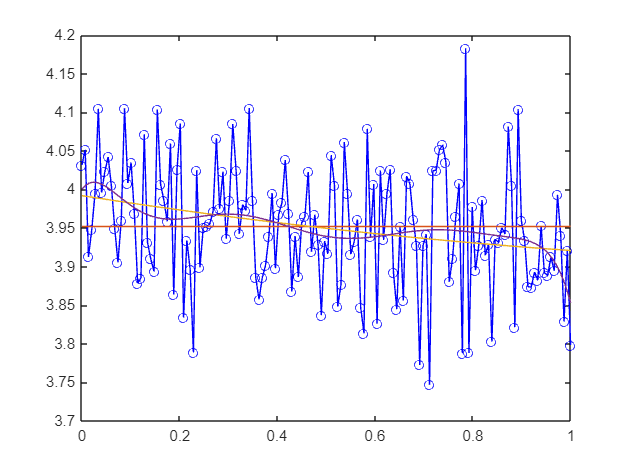


plot(ax,x,y,"-ob")
hold(ax,"on");hold(ax_hist,"on");hold(ax_res,"on");
y_hat = zeros(n,numel(p));
for ii = 1:numel(p)
    pps{ii} = polyfit(x,y,p(ii)-1);
    y_hat(:,ii) = polyval(pps{ii},x);
    cur_stat = descriptive_stat("y",y,"y_hat",y_hat(:,ii),"p",p(ii));
    stats{ii} = cur_stat;
    plot(ax,x,y_hat(:,ii))
    histogram(ax_hist,y - y_hat(:,ii),30,"Normalization","probability","FaceAlpha",0.3)
    plot(ax_res,x,y - y_hat(:,ii),"MarkerMode","auto")
end
hold(ax,"off");hold(ax_hist,"off");hold(ax_res,"off");

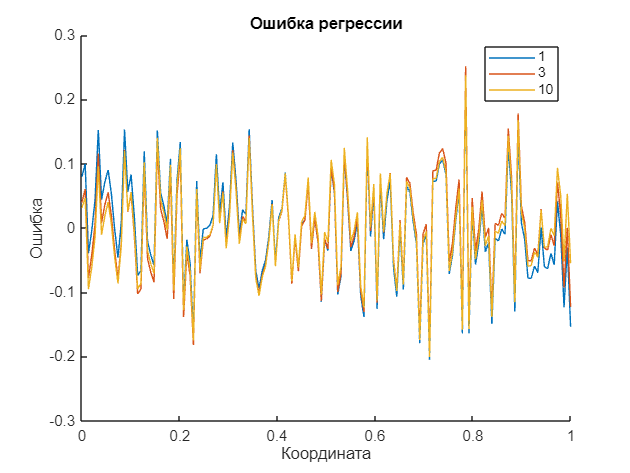

legend(ax_res, string(p)); ylabel(ax_res,"Ошибка");xlabel(ax_res,"Координата");title(ax_res,"Ошибка регрессии")

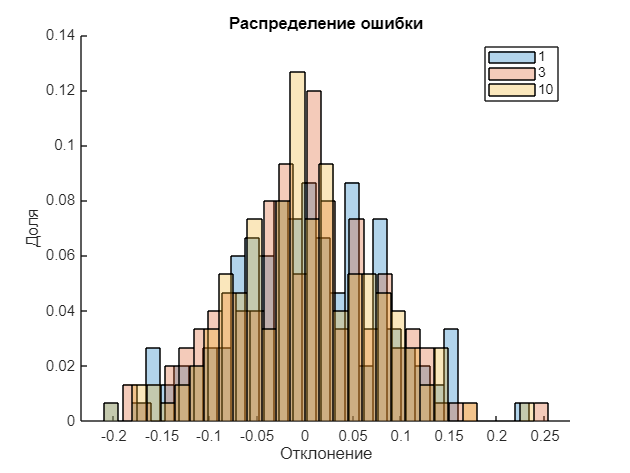

legend(ax_hist, string(p));ylabel(ax_hist,"Доля");xlabel(ax_hist,"Отклонение");title(ax_hist,"Распределение ошибки")


names = fieldnames(stats{1})

names = 8×1 cell array
    {'SSE'  }
    {'AIC'  }
    {'SST'  }
    {'BIC'  }
    {'r2'   }
    {'AICC' }
    {'r2adj'}
    {'RIC'  }


stat_data = zeros(numel(p),numel(names));
for ii = 1:numel(p)
    disp("p=" + p(ii))
    fitdist(y-y_hat(:,ii),"Normal")
    
    stat_data(ii,:) = cellfun(@(X)stats{ii}.(X),names);
end

p=1


ans =   NormalDistribution

  Normal distribution
       mu = -1.72011e-15   [-0.0127882, 0.0127882]
    sigma =    0.0792617   [0.0711932, 0.0894092]


p=3


ans =   NormalDistribution

  Normal distribution
       mu = -1.66385e-15   [-0.0123386, 0.0123386]
    sigma =    0.0764755   [0.0686906, 0.0862663]


p=10


ans =   NormalDistribution

  Normal distribution
       mu = 6.51331e-16   [-0.0121662, 0.0121662]
    sigma =   0.0754071   [0.067731, 0.0850611]



t = array2table(stat_data);
t.Properties.VariableNames = names;
t.Properties.RowNames = string(num2cell(p))

t = 3×8 table
            SSE        AIC        SST        BIC          r2         AICC       r2adj       RIC  
          _______    _______    _______    _______    __________    _______    _______    _______

    1     0.93608     -758.5    0.93608    -755.49    1.1102e-16    -760.47          1    -751.39
    3     0.87143    -763.21    0.93608    -754.18      0.069068    -769.04    0.92999    -741.76
    10    0.84725    -746.11    0.93608       -716      0.094898    -764.53      0.899     -674.9


axbar = get_next_ax();

fig176


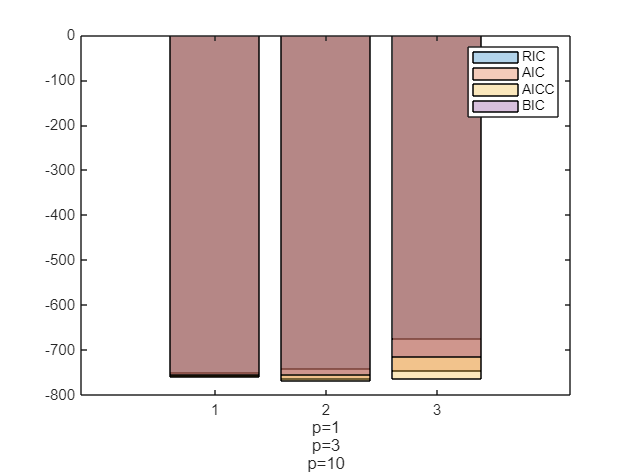

bar(axbar,t.RIC,"FaceAlpha",0.3);hold(axbar,"on")
bar(axbar,t.AIC,"FaceAlpha",0.3)
bar(axbar,t.AICC,"FaceAlpha",0.3)
bar(axbar,t.BIC,"FaceAlpha",0.3)
hold(axbar,"off");legend(axbar,["RIC","AIC","AICC","BIC"]);
%ylim(axbar,[-2500,-2200])
axbar.XLabel.String = cellstr(["p=" + p(1),"p=" + p(2),"p=" + p(3)]);

Поэтому выбор оптимальной модели основан на двух критериях: хорошего описания модели (малая амплитуда ошибки) и простоты выбранной модели (малое число параметров модели).

Для линейной регрессии существует несколько достаточно простых критериев, основаны на анализе  ошибки регрессии, в формулах ниже $k$ - это число параметров модели, $n$ - число точек.


$$\hat{\sigma}^2=\frac { \vec{r}^T\vec{r}} {n}$$


AIC: $n\mathrm{log}(\hat{\sigma}^2) + 2k + n(1+ln(2\pi))$ - Akaike information criteria

BIC: $n\mathrm{log}(\hat{\sigma}^2) + k\mathrm{log}(n) + n(1+log(2\pi))$ - Bayesian information criteria

AICc: $AIC + \frac{2k(k+1)}{n-k-1}$ -corrected Akaike information criteria

RIC: $(n-k)\mathrm{log}(\hat{\sigma}^2) + k[\mathrm{log}(n) - 1] + \frac{4} {n-k-2}$ (J.R.Statist.Soc.B 2002. pp. 237 - 252. Regression model selection  - a residual likelihood approach,  в статье формула выводится в более общем виде, который позволяет ее использовать для различного вида регрессий, так называемых **G**eneralized **L**inear **M**odel, для которых также как и для обычной линейной регерсии существуют аналитические решения)

AICf = @(n,k,s)n*log(s) + 2*k %+ n*(1 + log(2*pi))

AICf = function_handle with value:
    @(n,k,s)n*log(s)+2*k


BICf = @(n,k,s)n*log(s) + k*log(n) %+ n*(1 + log(2*pi))

BICf = function_handle with value:
    @(n,k,s)n*log(s)+k*log(n)


AICCf = @(n,k,s) n*log(s) + 2*k.*(k+1)./(n - k - 1);
RIC = @(n,k,s)(n-k)*log(s) + k*(log(n)-1)  + 4./(n - k - 2);
M = {AICf,BICf,AICCf,RIC};

n = 18;
k = 33;
r = 2.9;
s  = r/(n - k);
n_range = k+2:100;
k_range = 1:n-2;
s_range = 1e-4:1e-2:3;
lstr = ["AIC","BIC","AICC","RIC"]

lstr = 1×4 string array
    "AIC"    "BIC"    "AICC"    "RIC"


plot(n_range,AICf(n_range,k,s),"r", ...
    n_range,BICf(n_range,k,s),"g",...
    n_range,AICCf(n_range,k,s),"b",...
    n_range,RIC(n_range,k,s),"c",LineWidth=2)

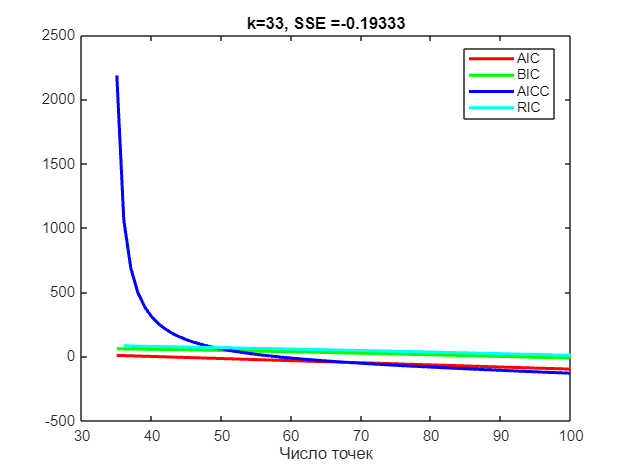

legend(lstr,"Location","best");xlabel("Число точек");title("k=" + string(k) + ", SSE =" + s)

plot(k_range,AICf(n,k_range,s),"r", ...
    k_range,BICf(n,k_range,s),"g",...
    k_range,AICCf(n,k_range,s),"b",...
    k_range,RIC(n,k_range,s),"c",LineWidth=2)

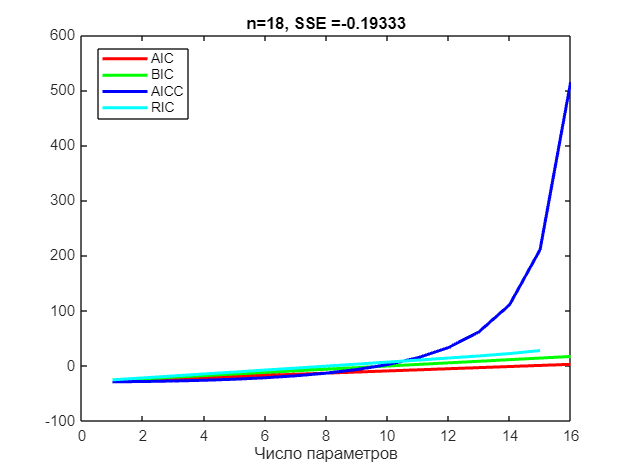

legend(lstr,"Location","best");xlabel("Число параметров");title("n=" + n + ", SSE =" + s)

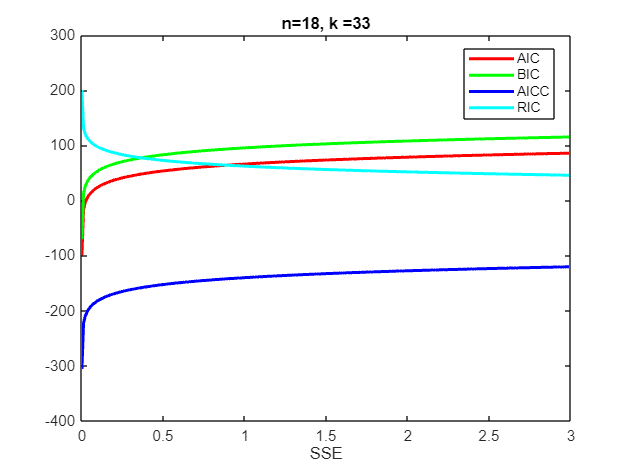

plot(s_range,AICf(n,k,s_range),"r", ...
    s_range,BICf(n,k,s_range),"g",...
    s_range,AICCf(n,k,s_range),"b",...
    s_range,RIC(n,k,s_range),"c",LineWidth=2)
legend(lstr,"Location","best");xlabel("SSE");title("n=" + n + ", k =" + k)


AICf = @(n,k,s)n*log(s) + 2*k %+ n*(1 + log(2*pi))

AICf = function_handle with value:
    @(n,k,s)n*log(s)+2*k


BICf = @(n,k,s)n*log(s) + k*log(n) %+ n*(1 + log(2*pi))

BICf = function_handle with value:
    @(n,k,s)n*log(s)+k*log(n)


AICCf = @(n,k,s) n*log(s) + 2*k.*(k+1)./(n - k - 1);
RIC = @(n,k,s)(n-k)*log(s) + k*(log(n)-1)  + 4./(n - k - 2);
M = {AICf,BICf,AICCf,RIC};


n = 100;
e = 17.65

e = 17.6500

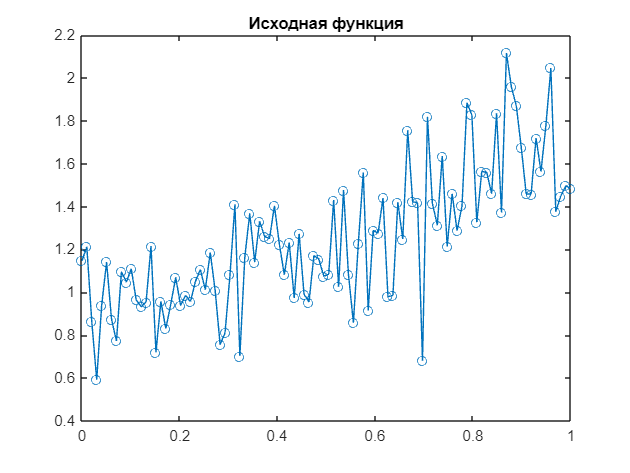

x = linspace(0,1,n)';
p_true = [8e-1, 1e-2,1];
k = [1,2,3,4,5,6,10];
m = length(M); % number of criteria
q = length(k);% number of models
y = cell(m ,1);
p = cell(m ,1);
r = zeros(m ,1);
y_true =  (1 + (e/100)*randn(n,1)).*polyval(p_true,x);

plot(x,y_true,"-o");title("Исходная функция")

for ii = 1:q
    ki = k(ii);
    p{ii} = polyfit(x,y_true,ki - 1);
    y{ii} = polyval(p{ii},x);
    r(ii) = sumsqr(y{ii} - y_true);
end
criteria_value = zeros(q,m);
for jj = 1:m
    cr_fun = M{jj};
    for ii = 1:q
        ki = k(ii);
        ri = r(ii)/(n-ki);
        criteria_value(ii,jj) =cr_fun(n,ki,ri);
    end
end
ax2 = get_next_ax();

fig177


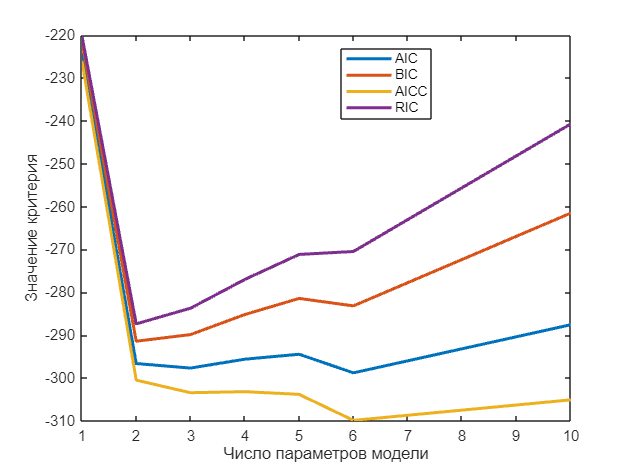

plot(ax2,k,criteria_value,LineWidth=2,MarkerMode="auto")
xlabel("Число параметров модели")
ylabel("Значение критерия")
legend(lstr,"Location","best");

% p2 = polyfit(x,y,2);y2 = polyval(p2,x);
% p3 = polyfit(x,y,3);y3 = polyval(p3,x);
% p4 = polyfit(x,y,4);y4 = polyval(p4,x);
% ax = get_next_ax();
% 
% plot(ax,x,y,"*r",...
%             x,y2,"-ob",...
%             x,y3,"-og",...
%             x,y4,"-ob")
% 
% 
% AIC_val = AIC(n,length(p))
% BICf = @(n,k,s)n*log(s) + k*log(n) %+ n*(1 + log(2*pi))
% AICCf = @(n,k,s) n*log(s) + 2*k.*(k+1)./(n - k - 1);
% RIC

### Планирование эксперимента.

Основная идея задачи планирования состоит в том, чтобы поставить эксперимент таким образом, чтобы уменьшить неопределенност в выходных параметрах (см формлуы для ковариации линейной и нелинейной регресии). Понятно, что неопределенност можно уменьшить увеличивая величину дисперсии исходных данных путем увеличения числа измерений, но это не всегда возможно, а вот повлиять постановкой эксперимента на величину матриц $A^TA$ и $J^TJ$ в принципе возможно.

Таким образом задача планирования эксперимента это оптимизационная задача по подбору условий получения исходных данных, таким образом, чтобы получить минимально возможную вариацию параметров.

#### Планирования эксперимента на примере линейной регрессии

Начнем с более простого варианта  - линейной регресии. 

Рассмотрим конкретный пример.

Для определенности, пусть у нас есть некоторый процесс, за которым мы можем наблюдать во времени, мы предполагаем, что этот процесс описывается кубическим полиномом  (в стандартном базисе) от времени, то есть, измеряемый датчиком отклик: $y = a_0 + a_1t + a_2t^2 + a_3t^3 + \zeta$, для простоты предположим, что ошибка измерений не зависит от времени, тогда можно пользоваться обычной регрессией. Пусть длительность процесса будет одна секунда  $t \in [0\dots1]$. Для наблюдения за процессом мы используем  автономный датчик, который может в течение  1 секунды снять только десять точек (после чего у него "садится" батарейка), зато частота расположения этих точек может быть произвольной,поэтому мы можем получить измерения для любых десяти моментов времени в пределах одной секунды. Задача проектирования эксперимента будет состоять в том, чтобы подобрать такую зависимость интервала между считываниями, чтобы получить минимальную вариацию параметров модели $\vec{a} = [a_0...a_3]$, то есть, найти такие моменты времени включения датчика $t_i$, которые позволят нам максимально достоверно (с наименьшей вариацией) оценить вектор параметров модели. 

Матрица предикторов для полиномиальной аппроксимации будет:


$$X = [I,\vec{t}, \vec{t}^2, \vec{t}^3]$$


Ковариация оценки параметров модели:


$$\mathrm{Cov}(\vec{a}) = (X^TX)^{-1}\sigma^2$$


Отсюда видно, что, чем "больше" и "устойчивей"  информационная матрица $X^TX$, тем "меньше" ковариация (а диагональные элементы этой матрицы - это вариация)  - меньше неопределенности нашей оценки параметров. Поэтому можно поставить оптимизационную задачу проектирования: найти такой набор параметров$\vec{\theta}$, который дает максимальную информационную матрицу  $X(\vec{\theta})^TX(\vec{\theta})$ или минимальную матрицу ковариации $\mathrm{Cov}(\vec{a}) \propto (X(\vec{\theta})^TX(\vec{\theta}))^{-1}$

Что такое "максимальная/минимальная" матрица, тут можно применить разные критерии:

-  D - оптимальность: Чем больше определитель информационной матрицы (меньше определитель обратной), тем меньше объем эллипсоида неопределенности: $\vec{\theta} = \mathrm{argmin( det((X^TX)^{-1})}$. Хотя уменьшение вариации это хорошо, но в данном критерии возможно появление неустойчивости  из-за большого 

-  K - оптимальность.Чем меньше conditional number (отношение максимального сингулярного знаечния к минимальному) информационной матрицы, тем более устойчиво ее обращение: $\vec{b} = \mathrm{argmin(cond(X^TX))$

- A - оптимальность. Чем меньше след обратной информационной матрицы, 

 Будем пытаться найти функцию, которая наилучшим семплирует из трех видов: первая  семплирование:

$\vec{t}^{uniform} = (\vec{i} - 1)/(n-1)$ - равномерное

$\vec{t}^{exp}(\gamma) = \frac {exp({\gamma\vec{t}^{uniform}) - 1}} {exp({\gamma) - 1}}$ - экспоненциальное с параметром $\gamma$

$\vec{t}^{cheb} =\frac{1}{2} cos(\frac{\pi(\vec{i}-1)}{n-1})$  - семплирование по Чебышеву


$$\vec{i} = [1\dots n]^T$$


Вообще данная задача, конечно уже давно решена, самую лучшую матрицу дает семплирование по Чебышеву с полиномами чебышева в качестве мономиалов, поэтому данный вариант мы будем рассматривать как эталонный

clearvars
X_fun = @(g,f) [ones(10,1),f(g),(f(g)).^2,(f(g)).^3]; % experiment matrix
inform_mat = @(g,f) ( X_fun(g,f)' *   X_fun(g,f));% information matrix
f_discr_cond = @(g,f) cond(inform_mat(g,f)); % minimizing conditional number
f_discr_det = @(g,f) det(inform_mat(g,f)\eye(4)); % 
f_discr_trace = @(g,f) trace(inform_mat(g,f)\eye(4));


n = 10; % number of sampling points
ii = (1:n)';
tmin = 0;
tmax = 1;
t0 = tmin + (tmax - tmin)*(ii - 1)/(n-1); % equally spaced sampling procedure
tcheb = chebyshev_nodes(n,tmin,tmax);
X_equally =[ones(10,1),t0,t0.^2,t0.^3]; % predictors for equally spaced sampling points
%X_cheb = [ones(10,1),tcheb,tcheb.^2,tcheb.^3];
X_cheb = cheb_vandermonde(tcheb,3)

X_cheb =     1.0000    1.0000    1.0000    1.0000
    1.0000    0.9698    0.8812    0.7394
    1.0000    0.8830    0.5595    0.1050
    1.0000    0.7500    0.1250   -0.5625
    1.0000    0.5868   -0.3113   -0.9522
    1.0000    0.4132   -0.6586   -0.9574
    1.0000    0.2500   -0.8750   -0.6875
    1.0000    0.1170   -0.9726   -0.3445
    1.0000    0.0302   -0.9982   -0.0904
    1.0000         0   -1.0000         0


gamma=4.171;
f_exp_spaced = @(gamma) tmin + (tmax - tmin)*(exp(gamma*t0) - 1)/(exp(gamma) -1);
ax = get_next_ax();

fig178


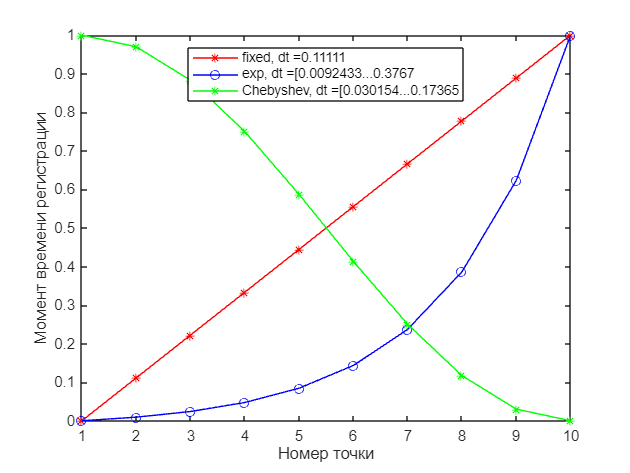

plot(ii,t0,"-*r")
hold on
plot(ax,ii,f_exp_spaced(gamma),"-ob")
plot(ax,ii,tcheb,"-*g")
hold off
ylabel("Момент времени регистрации")
xlabel("Номер точки")
legend(["fixed, dt ="+ (t0(2) - t0(1)), ...
    "exp, dt =[" + min(abs(diff(f_exp_spaced(gamma)))) + "..." + ...
    max(abs(diff(f_exp_spaced(gamma)))), ...
    "Chebyshev, dt =[" + min(abs(diff(tcheb))) + "..." + ...
    max(abs(diff(tcheb)))], "Location","best")


tt1 = table(sum(diag((X_equally'*X_equally)\eye(4))), ...
    sum(diag(inform_mat(gamma,f_exp_spaced)\eye(4))),...
    sum(diag((X_cheb'*X_cheb)\eye(4))));
tt1.Properties.VariableNames = {'uniform', 'exp spaced','Cheb'}

tt1 = 1×3 table
    uniform    exp spaced    Cheb 
    _______    __________    _____

    641.57       877.17      582.4


gamma

gamma = 4.1710

g_plot = -1:1e-3:5;
y1 = arrayfun(@(x)f_discr_cond(x,f_exp_spaced),g_plot);
plot(g_plot,y1/max(y1))
hold on
y2 = arrayfun(@(x)f_discr_det(x,f_exp_spaced),g_plot);

plot(g_plot,y2/max(y2))
y3 = arrayfun(@(x)f_discr_trace(x,f_exp_spaced),g_plot);

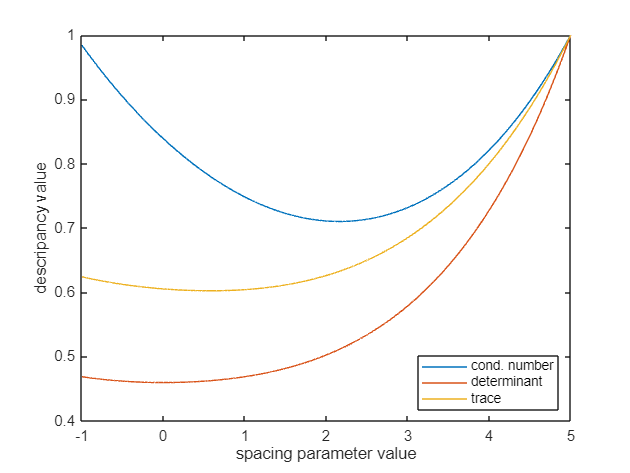

plot(g_plot,y3/max(y3))
hold off
legend(["cond. number","determinant","trace"],Location="best")
xlabel("spacing parameter value")
ylabel("descripancy value")

gamma_opt_cond = fminbnd(@(x)f_discr_cond(x,f_exp_spaced),-20,20)

gamma_opt_cond = 2.1614

gamma_opt_det = fminbnd(@(x)f_discr_det(x,f_exp_spaced),-20,20)

gamma_opt_det = 3.3333e-05

gamma_opt_trace = fminbnd(@(x)f_discr_trace(x,f_exp_spaced),-20,20)

gamma_opt_trace = 0.5754

ax2 = get_next_ax()

fig179


ax2 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


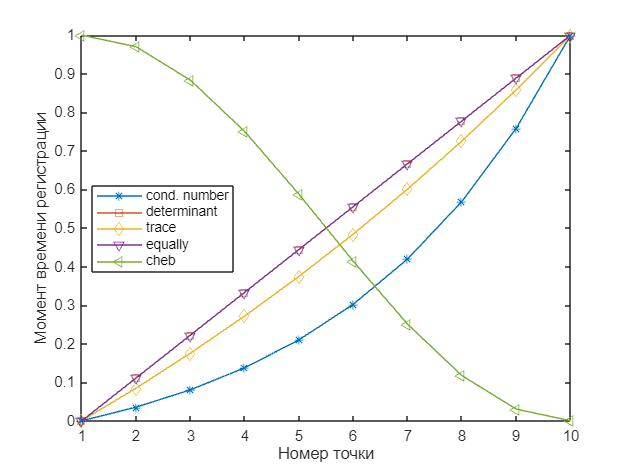

plot(ax2,ii,f_exp_spaced(gamma_opt_cond),"-*")
hold(ax2,"on")
plot(ax2,ii,f_exp_spaced(gamma_opt_det),"-square")
plot(ii,f_exp_spaced(gamma_opt_trace),"-diamond")
plot(ii,t0,"-v")
plot(ii,tcheb,"-<")
hold(ax2,"off")
legend("cond. number","determinant","trace","equally","cheb",Location="best")
ylabel("Момент времени регистрации")
xlabel("Номер точки")

% comparing conditional numbez of different 
disp("Conditional number cond(X'X):")

Conditional number cond(X'X):


disp("K-optimal: " + f_discr_cond(gamma_opt_cond,f_exp_spaced) )% 

K-optimal: 8300.2907


disp("D-optimal: " + f_discr_cond(gamma_opt_det,f_exp_spaced) )

D-optimal: 9806.1068


disp("A-optimal:" + f_discr_cond(gamma_opt_trace,f_exp_spaced))

A-optimal:9121.398


disp("Equally spaced:" +cond(X_equally'*X_equally))

Equally spaced:9806.1524


disp("Chebyshev spaced:" +cond(X_cheb'*X_cheb))

Chebyshev spaced:7917.4931


disp("")
% comparing conditional numbez of different 
disp("Total vaiance trace(X'X)^{-1}:")

Total vaiance trace(X'X)^{-1}:


disp("K-optimal: " + f_discr_trace(gamma_opt_cond,f_exp_spaced) )% 

K-optimal: 670.6088


disp("D-optimal: " + f_discr_trace(gamma_opt_det,f_exp_spaced) )

D-optimal: 641.5647


disp("A-optimal:" + f_discr_trace(gamma_opt_trace,f_exp_spaced))

A-optimal:638.4804


disp("Equally spaced:" +trace(inv(X_equally'*X_equally)))

Equally spaced:641.565


disp("Chebyshev spaced:" +trace(inv(X_cheb'*X_cheb)))

Chebyshev spaced:582.4038


#### Планирование эксперимента для обратной задачи теплопроводности

Обратная задача теплопроводности формулируется так:

По измеренным температурам от времени определить зависимость от температуры теплопроводности/теплоемкости граничных условий или начального распределения температур.

Теплофизический эксперимент имеет следующие "скрытые" параметры, которые оказывают влияние на точность решения обратной задачи и которые экспериментатор может варьировать :

- Режим нагрева, скорость нагрева , длительность полки нагрева

- Количество термопар

- Места расположения термопар по толщине образца

- Граничные условия снизу - температура холодильника, наличие теплоизоляционных слоев, излучательная способность поверхности

- Начальное распределение температуры в образце?

Так как ОЗ теплопроводности включает в себя подзадачу - решения нестационарного нелинейного уравнения в частных производных, то к вопросу планирования "эксперимента" можно также отнести ряд параметров решения дифференциального уравнения, например:

- Шаг сетки по времени

- Шаг сетки по координате

- Схема численного решения прямой задачи 

Задача планирования эксперимента - это отдельная оптимизационная задача, в которой в качестве переменных оптимизации выступают "скрытые" параметры эксперимента

Оптимизационная задача планирования теплофизического эксперимента - подобрать координаты расположения термопар таким образом, что определитель приближенного гессиана был максимальным на протяжении всего эксперимента

$\mathrm{Cov}(\vec{b^*}) =H^{-1}\zeta^2  \approx (J^T W^{-1} J)^{-1}\zeta^2$ - матрица ковариации, $\vec{b^*}$ - локальный минимум.

Таким образом, спланировать оптимально эксперимент можно исходя из упомянутых выше критериев минимальности, применяя их к приближенному гессиану ($J^TW^{-1}J$), рассчитанному в точке близкой к точке локального минимума, поэтому матрицу  Якоби  называют матрицей влияния:

-  D - оптимальность: Чем больше определитель информационной матрицы (меньше определитель обратной), тем меньше объем эллипсоида неопределенности: $\vec{\theta} = \mathrm{argmin( det((J^TW^{-1}J)^{-1})}$. Хотя уменьшение вариации это хорошо, но в данном критерии возможно появление неустойчивости  из-за большого 

-  K - оптимальность.Чем меньше conditional number (отношение максимального сингулярного знаечния к минимальному) информационной матрицы, тем более устойчиво ее обращение: $\vec{\theta} = \mathrm{argmin(cond(J^TW^{-1}J))$

- A - оптимальность. Чем меньше след обратной информационной матрицы, 

Так как, например, в задаче идентификации теплофизических свойств информационная матрица зависит от параметров оптимизации, чтобы провести планирование эксперимента до его проведения необходимо знать примерно какие теплофизические свойства материала. Так как при планировании, параметрами оптимизации уже будут параметры эксперимента, кроме того для расчета информационной матрицы, необходимо уметь дифференцировать функцию отклонения по параметрам оптимизации. Для вычисления матрицы Якоби могут применяться следующие способы:

- Аналитическое решение 

- Сопряженная задача - дифур для Якобиана

- Конечно-разностное дифференцирование

- Автодифференцирование 

- Метод Монте-Карло - метод М-К позволяет проследить распространение случаной величины через ОЗ 

FUNСTIONS

function D = Dt(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(0,M-1,M)) = -1;
    D(diagonal_inds(1,M-1,M)) = 1;
end
function D = Dtsym(M)
% M- number of input matrix rows
    D = zeros(M-1,M);
    D(diagonal_inds(-1,M-1,M)) = -1/2;
    D(diagonal_inds(1,M-1,M)) = 1/2;
end
function D = D2t(N)
    D = zeros(N,N);
    D(diagonal_inds(0,M-1,M)) = -2;
    D(diagonal_inds(1,M-1,M)) = 1; 
    D(diagonal_inds(-1,M-1,M)) = 1;
end
function indices = diagonal_inds(diagonal_index,rows_number, columns_number)
    % diagonalIndicesRect returns linear indices of the k-th diagonal of an m x n matrix
    % m - number of rows
    % n - number of columns
    % k - diagonal number (0 = main, >0 above main, <0 below main)
    %
    % Linear indices are returned for the elements along the specified diagonal,
    % respecting matrix dimensions.
    
    if diagonal_index >= 0
        % Diagonal above or on main
        len = min(rows_number, columns_number-diagonal_index);
        rowIdx = 1:len;
        colIdx = (1:len) + diagonal_index;
    else
        % Diagonal below main
        len = min(rows_number+diagonal_index, columns_number);
        rowIdx = (1:len) - diagonal_index;
        colIdx = 1:len;
    end
    
    % Convert row and column indices to linear indices for column-major order
    indices = sub2ind([rows_number columns_number], rowIdx, colIdx);
end
function t = chebyshev_nodes(n, tmin, tmax)
    % Chebyshev-Gauss-Lobatto nodes on [-1, 1]: cos(pi * (0:n-1)/(n-1))
    k = (0:n-1)';
    u = cos(pi * k / (n - 1));  % Includes endpoints u=±1
    
    % Affine map to [tmin, tmax]
    t = tmin + (tmax - tmin) * (u + 1) / 2;
end
function V = cheb_vandermonde(nodes, d)
    % CHEB_VANDERMONDE: Chebyshev basis Vandermonde (well-conditioned)
    n = length(nodes); V = zeros(n, d+1);
    V(:,1) = 1; V(:,2) = nodes;
    for k = 2:d
        V(:,k+1) = 2*nodes .* V(:,k) - V(:,k-1);  % T_k recurrence
    end
end
function [f,g] = rosen(x)
f = 100*(x(1) - x(2)^2)^2 + (1 - x(2))^2;
if nargout > 1
    g(1) = 200*(x(1) - x(2)^2);
    g(2) = -400*x(2)*(x(1) - x(2)^2) - 2*(1 - x(2));
end
end